# Autocorrelation in timeseries

A timeseries is autocorrelated if the value at each timepoint depends on values at previous timepoints. Timeseries which are autocorrelated tend to be correlated with each other, regardless of whether or not they are actually related or interacting in any way. In other words, there is a high false positive rate for correlations among independent timeseries.

In this tutorial, we generate timeseries which are independent, but appear correlated. We show how autoregression can be used to mitigate this confounding effect.

First, generate independent random walks:


$$X_t =X_{t-1} +\varepsilon_t$$


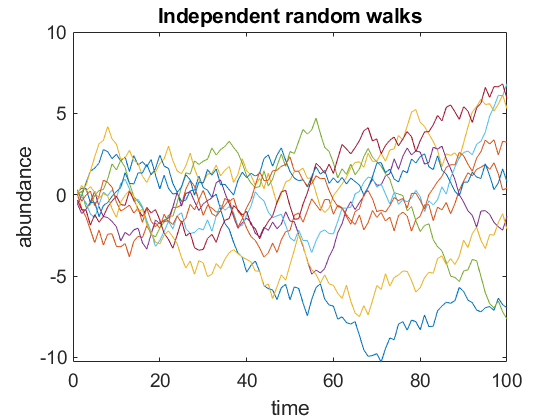

clear;

N = 10; % number of timeseries
NT = 100; % number of timepoints
epsilon = 2*rand(NT,N)-1; % random numbers between -1 and +1

% phi controls the strength of autocorrelation
% |phi|=1 -> random walk, highly autocorrelated
% |phi|=0 -> noise, not autocorrelated
% (note: |phi|>1 will generate divergent timeseries)
phi = 1;
if abs(phi)>1; fprintf('WARNING: timeseries will be divergent!\n'); end

% generate random walks
X = zeros(NT,N);
X(1,:) = epsilon(1,:);
for i = 2:NT
    X(i,:) = phi*X(i-1,:) + epsilon(i,:);
end

figure();
plot(X);
xlabel('time');
ylabel('abundance');
title('Independent random walks');
set(gca,'FontSize',14);

Some of the random walks appear highly correlated (and anticorrelated), despite being independent. Significant correlations (p<0.05) are marked with black stars.

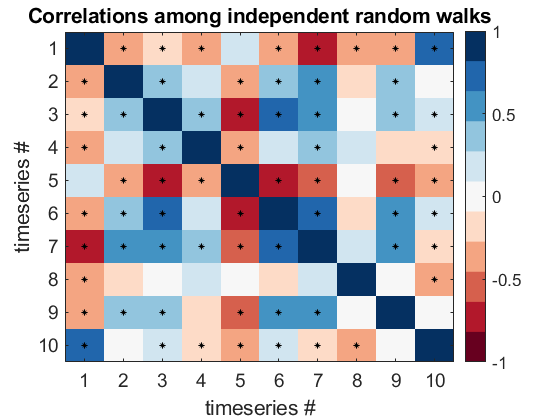

[rho_X, pval_X] = corr(X);

figure();
plot_correlation(rho_X,pval_X);
title('Correlations among independent random walks');

Here's an example of a highly correlated, yet independent pair:

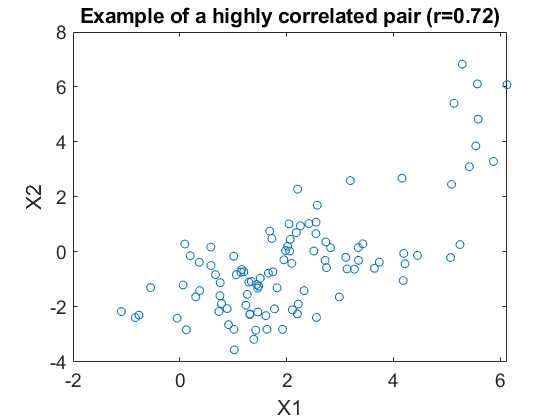

% find the most highly correlated pair
rho_offdiag = rho_X;
rho_offdiag(logical(eye(N))) = 0; % ignore self-correlation (which is always 1)
[~,maxID] = max(rho_offdiag(:));
[maxID1, maxID2] = ind2sub(size(rho_X),maxID);

figure();
plot(X(:,maxID1),X(:,maxID2),'o');
xlabel('X1');
ylabel('X2');
title(sprintf('Example of a highly correlated pair (r=%.2f)',rho_X(maxID)));
set(gca,'FontSize',14);

Our goal is to remove the autocorrelated component of each timeseries. Since these are random walks, each timepoint depends only on the one immediately before it. We can double check this by computing the partial autocorrelation for an example timeseries.

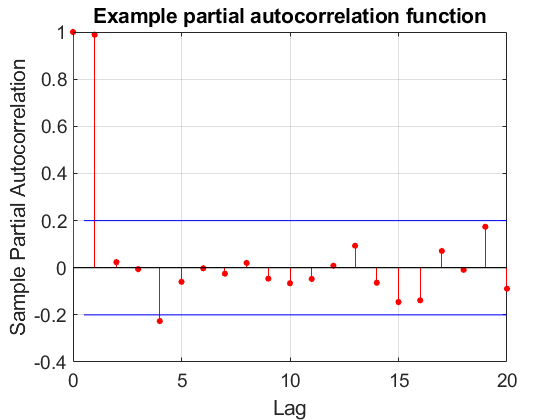

figure();
parcorr(X(:,1));
title('Example partial autocorrelation function');
set(gca,'FontSize',14);

We see that only the first two components (lag=0 and lag=1) are important. 

This means we want an AR(1) model:


$$X_t =c+\phi_1 X_{t-1} +\varepsilon_t$$


where $\phi_1$ is the autoregressive coefficient. Since we only need to compute one autoregressive coefficient, $\phi_1$, wewill compute it directly instead of using Matlab's arima model. The exact expression for $\phi_1$ is:


$$\phi_1 =\frac{\gamma_1 }{\gamma_0 }$$


where $\gamma_0$ is the autocovariance of $X$and $\gamma_1$ is the covariance of $X$ with itself delayed by one timestep.

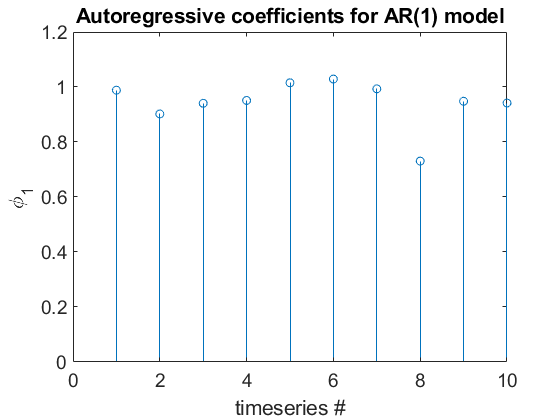

X1 = X(1:end-1,:);
X2 = X(2:end,:);
phi1_X = sum((X1-mean(X1)).*(X2-mean(X2)))./sum(X1.^2-mean(X1).^2);

figure();
stem(phi1_X,'o');
xlabel('timeseries #');
ylabel('\phi_1');
title('Autoregressive coefficients for AR(1) model');
set(gca,'FontSize',14);

We see that $\phi_1 \approx 1$ for all of the timeseries. This explains why we saw strong correlations (and anticorrelations) earlier.

Now we compute the residuals, that is, what's left from the original timeseries after the autoregressive component is removed.

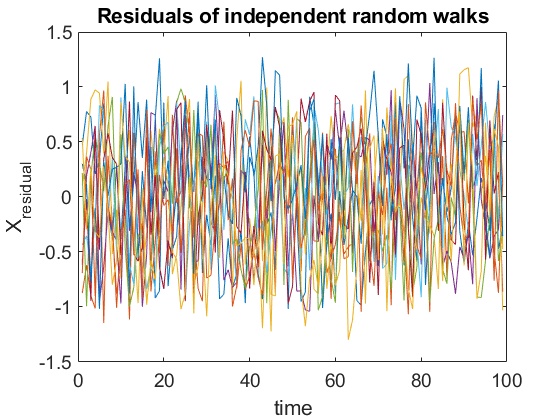

Xresidual = X2 - X1.*phi1_X;

figure();
plot(Xresidual);
xlabel('time');
ylabel('X_{residual}');
title('Residuals of independent random walks');
set(gca,'FontSize',14);

Let's look at that same "highly correlated" pair from before. This time, we'll plot the residual timeseries. We can clearly see that the pair is not correlated at all!

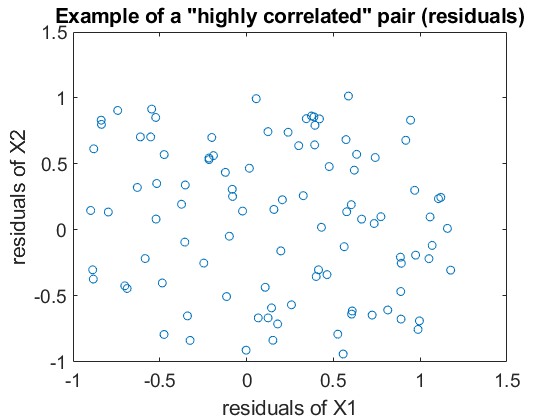

figure();
plot(Xresidual(:,maxID1),Xresidual(:,maxID2),'o');
xlabel('residuals of X1');
ylabel('residuals of X2');
title('Example of a "highly correlated" pair (residuals)');
set(gca,'FontSize',14);

Now, we compute the correlations for all the pairs of residual timeseries. Unlike before, independent random walks are no longer correlated.

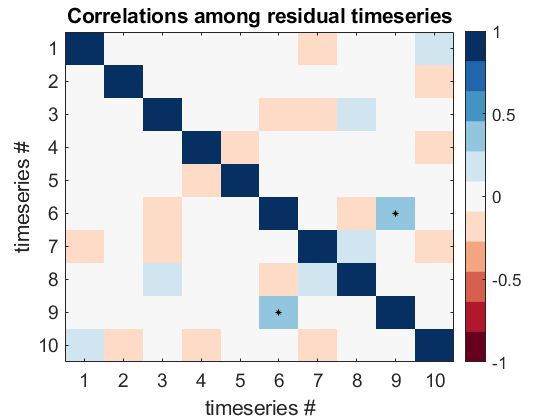

[rho_Xresidual, pval_Xresidual] = corr(Xresidual);

figure();
plot_correlation(rho_Xresidual,pval_Xresidual);
title('Correlations among residual timeseries');

Of course, it's still possible to get non-zero, significant correlations between independent timeseries. One good practice is to use more stringent conditions for singificance (e.g. Bonferroni correction for multiple comparisons). Another is to disregard correlations that are below a certain threshold magnitude.